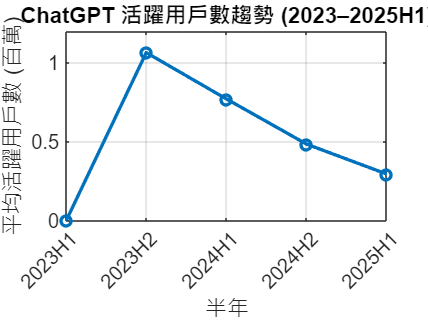

% 載入數據集
data = readtable('deepseek_vs_chatgpt_org.csv', 'VariableNamingRule', 'preserve');

% 提取年份和月份從 Date 欄位
data.Year = year(data.Date);
data.Month = month(data.Date);

% 生成半年標識（1-6 月為上半年，7-12 月為下半年）
data.HalfYear = cell(height(data), 1);
for i = 1:height(data)
    if data.Month(i) <= 6
        data.HalfYear{i} = sprintf('%dH1', data.Year(i));
    else
        data.HalfYear{i} = sprintf('%dH2', data.Year(i));
    end
end

% 過濾 2023-2025 年上半年數據
data = data(data.Year >= 2023 & (data.Year < 2025 | (data.Year == 2025 & data.Month <= 6)), :);

% 定義半年範圍
half_years = {'2023H1', '2023H2', '2024H1', '2024H2', '2025H1'};

% --- 圖表一和圖表二：活躍用戶數 ---
% 按半年和 AI_Platform 分組，計算平均 Active_Users
grouped_data_active = groupsummary(data, {'HalfYear', 'AI_Platform'}, 'mean', 'Active_Users');

% 初始化數據數組
chatgpt_users = zeros(size(half_years));
deepseek_users = zeros(size(half_years));

% 提取 ChatGPT 和 DeepSeek 的活躍用戶數
for i = 1:length(half_years)
    half_year_mask = strcmp(grouped_data_active.HalfYear, half_years{i});
    chatgpt_mask = strcmp(grouped_data_active.AI_Platform, 'ChatGPT');
    deepseek_mask = strcmp(grouped_data_active.AI_Platform, 'DeepSeek');

    if any(half_year_mask & chatgpt_mask)
        chatgpt_users(i) = grouped_data_active.mean_Active_Users(half_year_mask & chatgpt_mask);
    end
    if any(half_year_mask & deepseek_mask)
        deepseek_users(i) = grouped_data_active.mean_Active_Users(half_year_mask & deepseek_mask);
    end
end

% 將用戶數轉換為百萬單位以提高可讀性
chatgpt_users = chatgpt_users / 1e6;
deepseek_users = deepseek_users / 1e6;

% 圖表一：ChatGPT 活躍用戶數趨勢
figure;
plot(1:length(half_years), chatgpt_users, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0, 0.4470, 0.7410]);
xlabel('半年');
ylabel('平均活躍用戶數 (百萬)');
title('ChatGPT 活躍用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);

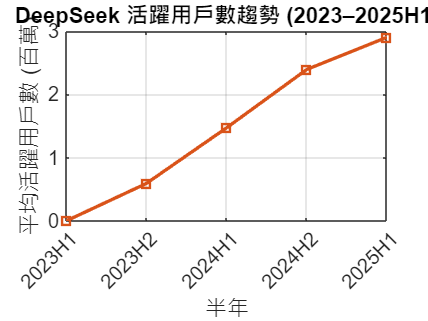


% 圖表二：DeepSeek 活躍用戶數趨勢
figure;
plot(1:length(half_years), deepseek_users, '-s', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.8500, 0.3250, 0.0980]);
xlabel('半年');
ylabel('平均活躍用戶數 (百萬)');
title('DeepSeek 活躍用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);

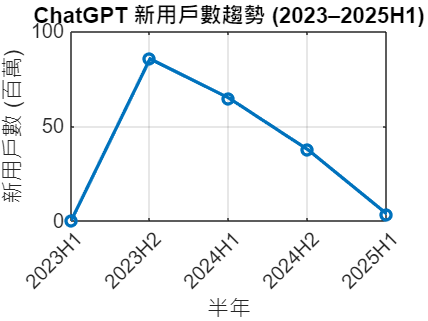


% --- 圖表三和圖表四：新用戶數 ---
% 按半年和 AI_Platform 分組，計算 New_Users 的總和
grouped_data_new = groupsummary(data, {'HalfYear', 'AI_Platform'}, 'sum', 'New_Users');

% 初始化數據數組
chatgpt_new = zeros(size(half_years));
deepseek_new = zeros(size(half_years));

% 提取 ChatGPT 和 DeepSeek 的新用戶數
for i = 1:length(half_years)
    half_year_mask = strcmp(grouped_data_new.HalfYear, half_years{i});
    chatgpt_mask = strcmp(grouped_data_new.AI_Platform, 'ChatGPT');
    deepseek_mask = strcmp(grouped_data_new.AI_Platform, 'DeepSeek');

    if any(half_year_mask & chatgpt_mask)
        chatgpt_new(i) = grouped_data_new.sum_New_Users(half_year_mask & chatgpt_mask);
    end
    if any(half_year_mask & deepseek_mask)
        deepseek_new(i) = grouped_data_new.sum_New_Users(half_year_mask & deepseek_mask);
    end
end

% 將用戶數轉換為百萬單位以提高可讀性
chatgpt_new = chatgpt_new / 1e6;
deepseek_new = deepseek_new / 1e6;

% 圖表三：ChatGPT 新用戶數趨勢
figure;
plot(1:length(half_years), chatgpt_new, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0, 0.4470, 0.7410]);
xlabel('半年');
ylabel('新用戶數 (百萬)');
title('ChatGPT 新用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);

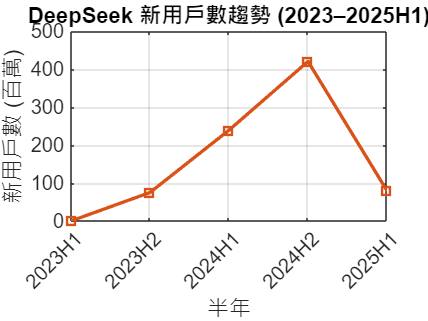


% 圖表四：DeepSeek 新用戶數趨勢
figure;
plot(1:length(half_years), deepseek_new, '-s', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.8500, 0.3250, 0.0980]);
xlabel('半年');
ylabel('新用戶數 (百萬)');
title('DeepSeek 新用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);

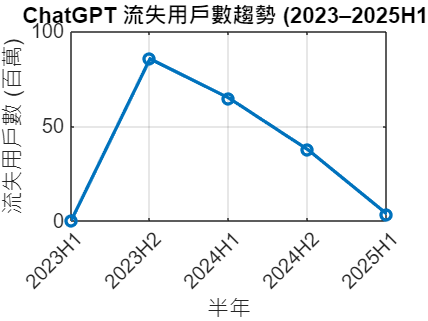


% --- 圖表五和圖表六：流失用戶數 ---
% 按半年和 AI_Platform 分組，計算 Churned_Users 的總和
grouped_data_churn = groupsummary(data, {'HalfYear', 'AI_Platform'}, 'sum', 'Churned_Users');

% 初始化數據數組
chatgpt_churn = zeros(size(half_years));
deepseek_churn = zeros(size(half_years));

% 提取 ChatGPT 和 DeepSeek 的流失用戶數
for i = 1:length(half_years)
    half_year_mask = strcmp(grouped_data_churn.HalfYear, half_years{i});
    chatgpt_mask = strcmp(grouped_data_churn.AI_Platform, 'ChatGPT');
    deepseek_mask = strcmp(grouped_data_churn.AI_Platform, 'DeepSeek');

    if any(half_year_mask & chatgpt_mask)
        chatgpt_churn(i) = grouped_data_churn.sum_Churned_Users(half_year_mask & chatgpt_mask);
    end
    if any(half_year_mask & deepseek_mask)
        deepseek_churn(i) = grouped_data_churn.sum_Churned_Users(half_year_mask & deepseek_mask);
    end
end

% 將用戶數轉換為百萬單位以提高可讀性
chatgpt_churn = chatgpt_churn / 1e6;
deepseek_churn = deepseek_churn / 1e6;

% 圖表五：ChatGPT 流失用戶數趨勢
figure;
plot(1:length(half_years), chatgpt_churn, '-o', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0, 0.4470, 0.7410]);
xlabel('半年');
ylabel('流失用戶數 (百萬)');
title('ChatGPT 流失用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);

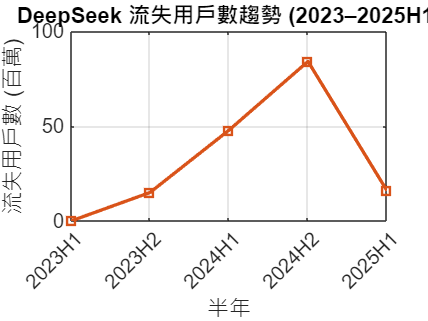


% 圖表六：DeepSeek 流失用戶數趨勢
figure;
plot(1:length(half_years), deepseek_churn, '-s', 'LineWidth', 2, 'MarkerSize', 6, 'Color', [0.8500, 0.3250, 0.0980]);
xlabel('半年');
ylabel('流失用戶數 (百萬)');
title('DeepSeek 流失用戶數趨勢 (2023–2025H1)');
set(gca, 'XTick', 1:length(half_years), 'XTickLabel', half_years, 'XTickLabelRotation', 45);
grid on;
set(gca, 'FontSize', 12);